# PRÁCTICA 1: Introducción a Matlab

## Matrices

A = [1,1,1];
size(A);
A = [1;1;1];
A = [1,2,3;4,5,6;7,8,9];
A = A';
A(2,3);
A = 0:0.1:10;
A = linspace(0,10,11);

## Plots

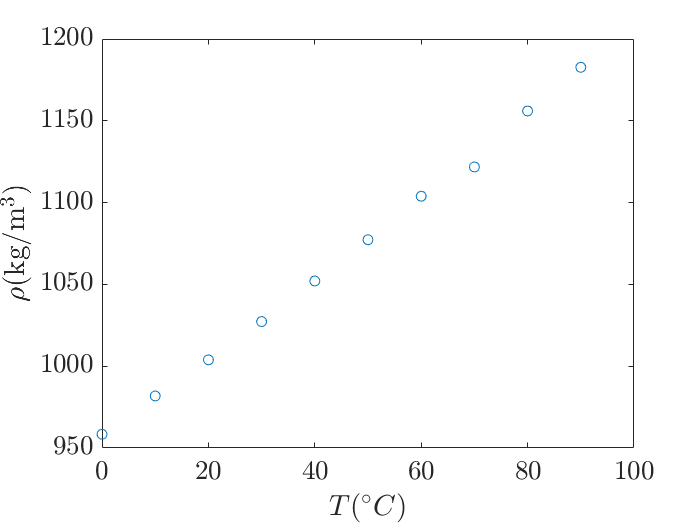

%%
% Carga los datos en la matriz A
A = [0 958.4 12.0700
    10 981.8 3.9000
    20 1003.9 1.4100
    30 1027.3 0.6120
    40 1052.1 0.2840
    50 1077.3 0.1420
    60 1103.9 0.0813
    70 1121.8 0.0506
    80 1156.0 0.0319
    90 1182.7 0.0213];
T = A(:,1);
rho = A(:,2);
mu = A(:,3);
% Pintar en dos figuras distintas, una con marcador y otra con marcador y
% líneas
figure(1)
plot(T,rho,'o')
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\rho$(kg/m$^3$)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)

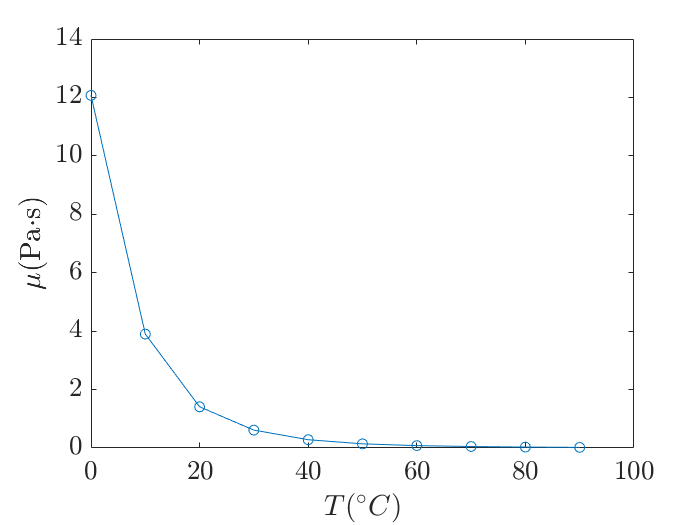

figure(2)
plot(T,mu,'o-')
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\mu$(Pa$\cdot$s)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)

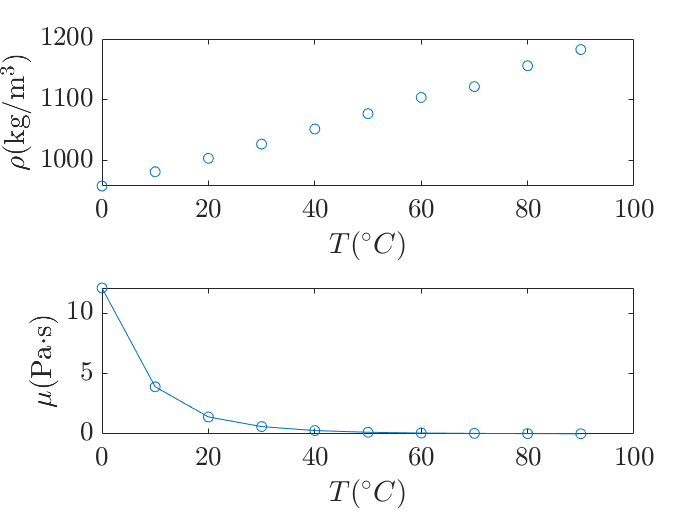

%%
% Pintar en la misma figura
figure(3)
subplot(2,1,1)
plot(T,rho,'o')
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\rho$(kg/m$^3$)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
subplot(2,1,2)
plot(T,mu,'o-')
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\mu$(Pa$\cdot$s)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)

## Interpolación y Aproximación

help interp1

 interp1 1-D interpolation (table lookup)
 
    Vq = interp1(X,V,Xq) interpolates to find Vq, the values of the
    underlying function V=F(X) at the query points Xq. 
 
    X must be a vector. The length of X is equal to N.
    If V is a vector, V must have length N, and Vq is the same size as Xq.
    If V is an array of size [N,D1,D2,...,Dk], then the interpolation is
    performed for each D1-by-D2-by-...-Dk value in V(i,:,:,...,:). If Xq
    is a vector of length M, then Vq has size [M,D1,D2,...,Dk]. If Xq is 
    an array of size [M1,M2,...,Mj], then Vq is of size
    [M1,M2,...,Mj,D1,D2,...,Dk].
 
    Vq = interp1(V,Xq) assumes X = 1:N, where N is LENGTH(V)
    for vector V or SIZE(V,1) for array V.
 
    Interpolation is the same operation as "table lookup".  Described in
    "table lookup" terms, the "table" is [X,V] and interp1 "looks-up"
    the elements of Xq in X, and, based upon their location, returns
   

help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains fields for the triangular factor (R) from a QR
    decomposition of the Vandermonde matrix of X, the degrees of freedom
    (df), and the norm of the residuals (normr).  If the data Y are random,
    an estimate of the covariance matrix of P is (Rinv*Rinv')*normr^2/df,
    where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit(X,Y,N) finds the coefficients of a polynomial in
    XHAT = (X-MU(1))/MU(2) where MU(1) = MEAN(X) and MU(2) = STD(X)

### Interpolación

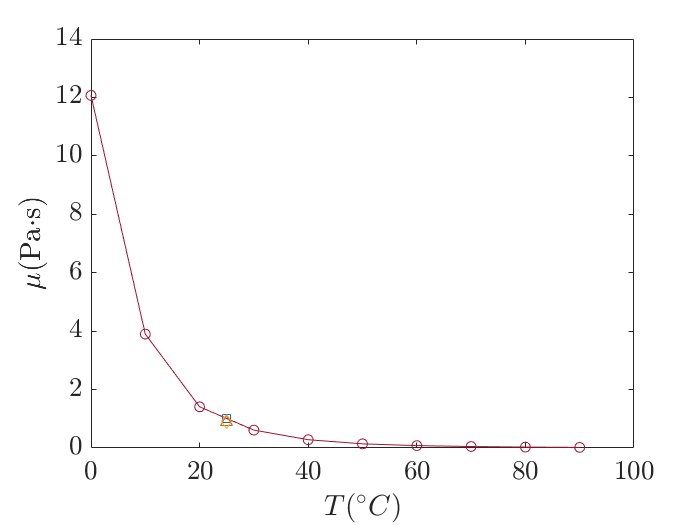

figure(5)
T0 = 25;
plot(T,mu,'o-')
hold on
mu_lineal = interp1(T,mu,T0);
mu_cubic = interp1(T,mu,T0,'cubic');
mu_spline = interp1(T,mu,T0,'spline');
plot(T0,mu_lineal,'s',T0,mu_cubic,'^',T0,mu_spline','d')
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\mu$(Pa$\cdot$s)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)

### Aproximación

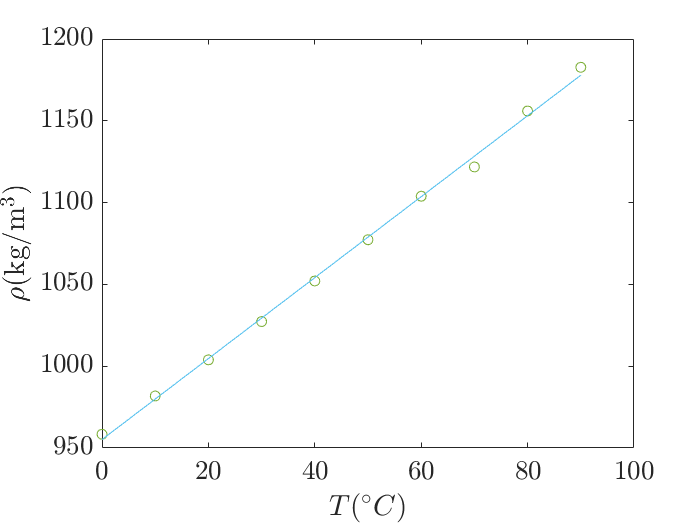

%%
figure(6)
T0 = 25;
plot(T,rho,'o')
hold on
% Al ser un polinomio lineal se le indica que el grado del mismo es 1
p = polyfit(T,rho,1);
rho_approx = polyval(p,T);
plot(T,rho_approx)
xlabel('$T(^\circ C)$','Interpreter','LaTeX','FontSize',16)
ylabel('$\rho$(kg/m$^3$)','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16) % gca= get current axis

help set

 set    Set object properties.
    set(H,'PropertyName',PropertyValue) sets the value of the specified
    property for the graphics object with handle H.  H can be a vector of 
    handles, in which case set sets the properties' values for all objects
    of H.
 
    set(H,a) where a is a structure whose field names are object property
    names, sets the properties named in each field name with the values
    contained in the structure.
 
    set(H,pn,pv) sets the named properties specified in the cell array of
    strings pn to the corresponding values in the cell array pv for all
    objects specified in H.  The cell array pn must be 1-by-N, but the cell
    array pv can be M-by-N where M is equal to length(H) so that each
    object will be updated with a different set of values for the list of 
    property names contained in pn.
 
    set(H,'PropertyName1',PropertyValue1,'Proper

rho_approx_25 = polyval(p,T0);
disp(['La densidad a ',num2str(T0),'ºC es de ',num2str(rho_approx_25),'kg/m^3'])

La densidad a 25ºC es de 1017.0339kg/m^3
